# Thermal Stress Analysis of Jet Engine Turbine Blade

This example shows how to compute the thermal stress and deformation of a turbine blade in its steady-state operating condition. The blade has interior cooling ducts. The cool air flowing through the ducts maintains the temperature of the blade within the limit for its material. This feature is common in modern blades.

A turbine is a component of the jet engine. It is responsible for extracting energy from the high-temperature and high-pressure gas produced in the combustion chamber and transforming it into rotational motion to produce thrust. The turbine is a radial array of blades typically made of nickel alloys. These alloys resist the extremely high temperatures of the gases. At such temperatures, the material expands significantly, producing mechanical stress in the joints and significant deformations of several millimeters. To avoid mechanical failure and friction between the tip of the blade and the turbine casing, the blade design must account for the stress and deformations.

The example shows a three-step workflow:

- Perform structural analysis accounting only for pressure of the surrounding gases while ignoring thermal effects.

- Compute the thermal stress while ignoring the pressure.

- Combine the pressure and thermal stress.

## Pressure Loading

The blade experiences high pressure from the surrounding gases. Compute the stress caused only by this pressure.

First, create a static structural model.

smodel = createpde("structural","static-solid");

Import and plot the geometry, displaying face labels.

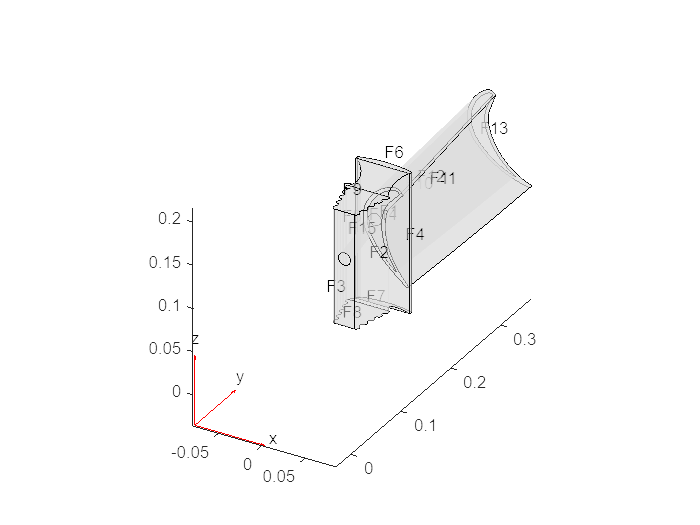

importGeometry(smodel,"Blade.stl");
figure
pdegplot(smodel,"FaceLabels","on","FaceAlpha",0.5)

Generate a mesh with the maximum element size 0.01.

msh = generateMesh(smodel,"Hmax",0.01);

Specify Young's modulus, Poisson's ratio, and the coefficient of thermal expansion for nickel-based alloy (NIMONIC 90).

E = 227E9; % in Pa
CTE = 12.7E-6; % in 1/K
nu = 0.27; 

structuralProperties(smodel,"YoungsModulus",E, ...
                            "PoissonsRatio",nu, ...
                            "CTE",CTE);

Specify that the face of the root that is in contact with other metal is fixed.

structuralBC(smodel,"Face",3,"Constraint","fixed");

Specify the pressure load on the pressure and suction sides of the blade. This pressure is due to the high-pressure gas surrounding these sides of the blade.

p1 = 5e5; %in Pa
p2 = 4.5e5; %in Pa

structuralBoundaryLoad(smodel,"Face",11,"Pressure",p1); % Pressure side
structuralBoundaryLoad(smodel,"Face",10,"Pressure",p2);  % Suction side 

Solve the structural problem.

Rs = solve(smodel);

Plot the von Mises stress and the displacement. Specify a deformation scale factor of 100 to better visualize the deformation.

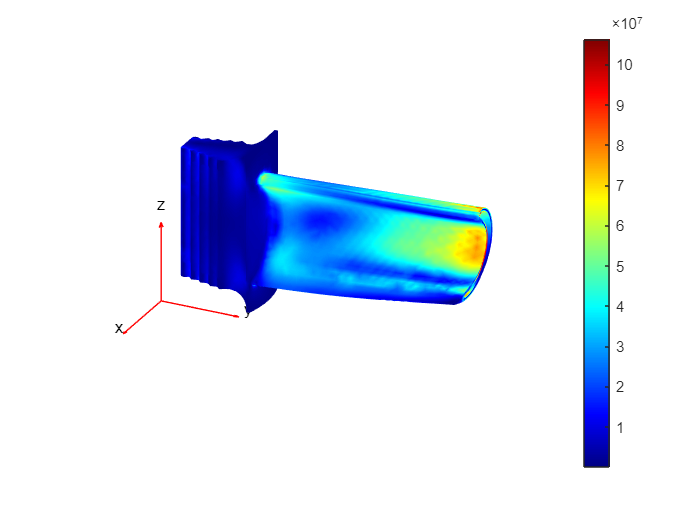

figure
pdeplot3D(smodel,"ColorMapData",Rs.VonMisesStress, ...
                 "Deformation",Rs.Displacement, ...
                 "DeformationScaleFactor",100)
view([116,25]);

The maximum stress is around 100 Mpa, which is significantly below the elastic limit.

## Thermal Stress

Determine the temperature distribution and compute the stress and deformation due to thermal expansion only. This part of the example ignores the pressure.

First, create a thermal model for steady-state thermal analysis.

tmodel = createpde("thermal","steadystate");

Import the same geometry and use the same mesh as for the structural analysis.

importGeometry(tmodel,"Blade.stl");
tmodel.Mesh = msh;

Assuming that the blade is made of nickel-based alloy (NIMONIC 90), specify the thermal conductivity.

kapp = 11.5; % in W/m/K
thermalProperties(tmodel,"ThermalConductivity",kapp);

Convective heat transfer between the surrounding fluid and the faces of the blade defines the boundary conditions for this problem. The convection coefficient is greater where the gas velocity is higher. Also, the gas temperature is different around different faces. The temperature of the interior cooling air is ${150}^{\circ } C$, while the temperature on the pressure and suction sides is ${1000}^{\circ } C$.

% Interior cooling
thermalBC(tmodel,"Face",[15 12 14], ...
                 "ConvectionCoefficient",30, ...  % h_air
                 "AmbientTemperature",150);  % T_air = 150
% Pressure side
thermalBC(tmodel,"Face",11, ...
                 "ConvectionCoefficient",50, ... % h_gas_pressureside = 50
                 "AmbientTemperature",1000); % T_gas = 1000
% Suction side             
thermalBC(tmodel,"Face",10, ...
                 "ConvectionCoefficient",40, ... % h_gas_suctionside = 40
                 "AmbientTemperature",1000); % T_gas = 1000
% Tip
thermalBC(tmodel,"Face",13, ...
                 "ConvectionCoefficient",20, ... % h_gas_tip = 20
                 "AmbientTemperature",1000); % T_gas = 1000
% Base (exposed to hot gases)
thermalBC(tmodel,"Face",1, ...
                 "ConvectionCoefficient",40, ...
                 "AmbientTemperature",800);
% Root in contact with hot gases
thermalBC(tmodel,"Face",[6 9 8 2 7], ...
                 "ConvectionCoefficient",15, ...
                 "AmbientTemperature",400);

The boundary condition for the faces of the root in contact with other metal is a thermal contact that can be modeled as convection with a very large coefficient (around $1000\;W/\left(m^2 K\right)$ for metal-metal contact).

% Root in contact with metal
thermalBC(tmodel,"Face",[3 4 5], ...
                 "ConvectionCoefficient",1000, ...
                 "AmbientTemperature",300);

Solve the thermal model.

Rt = solve(tmodel);

Plot the temperature distribution. The temperature between the tip and the root ranges from around ${820}^{\circ } C$ to ${330}^{\circ } C$. The exterior gas temperature is ${1000}^{\circ } C$. The interior cooling is efficient: it significantly lowers the temperature.

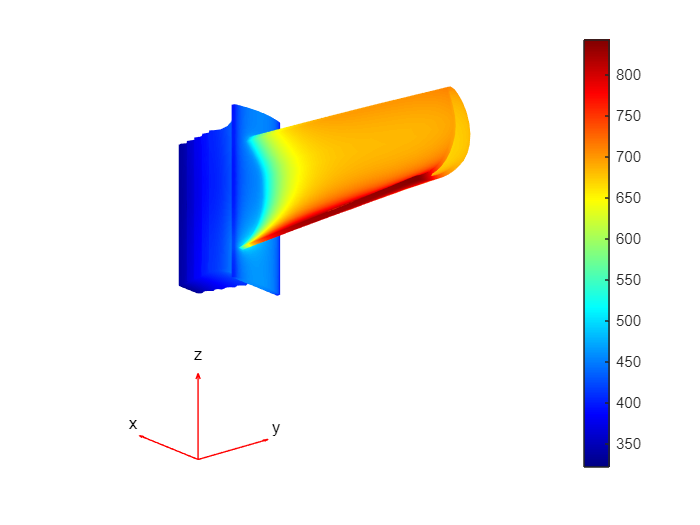

figure
pdeplot3D(tmodel,"ColorMapData",Rt.Temperature)
view([130,-20]);

Now, create a static structural model to compute the stress and deformation due to thermal expansion.

tsmodel = createpde("structural","static-solid");

Import the same geometry, and use the same mesh and structural properties of the material as for the structural analysis.

importGeometry(tsmodel,"Blade.stl");
tsmodel.Mesh = msh;
structuralProperties(tsmodel,"YoungsModulus",E, ...
                             "PoissonsRatio",nu, ...
                             "CTE",CTE);

Specify the reference temperature.

tsmodel.ReferenceTemperature = 300; %in degrees C
structuralBodyLoad(tsmodel,"Temperature",Rt);

Specify the boundary condition.

structuralBC(tsmodel,"Face",3,"Constraint","fixed");

Solve the thermal stress problem.

Rts = solve(tsmodel);

Plot the von Mises stress and the displacement. Specify a deformation scale factor of 100 to better visualize the deformation. The stress concentrates in the constrained root because it cannot freely expand, and also in the junction between the blade and the root.

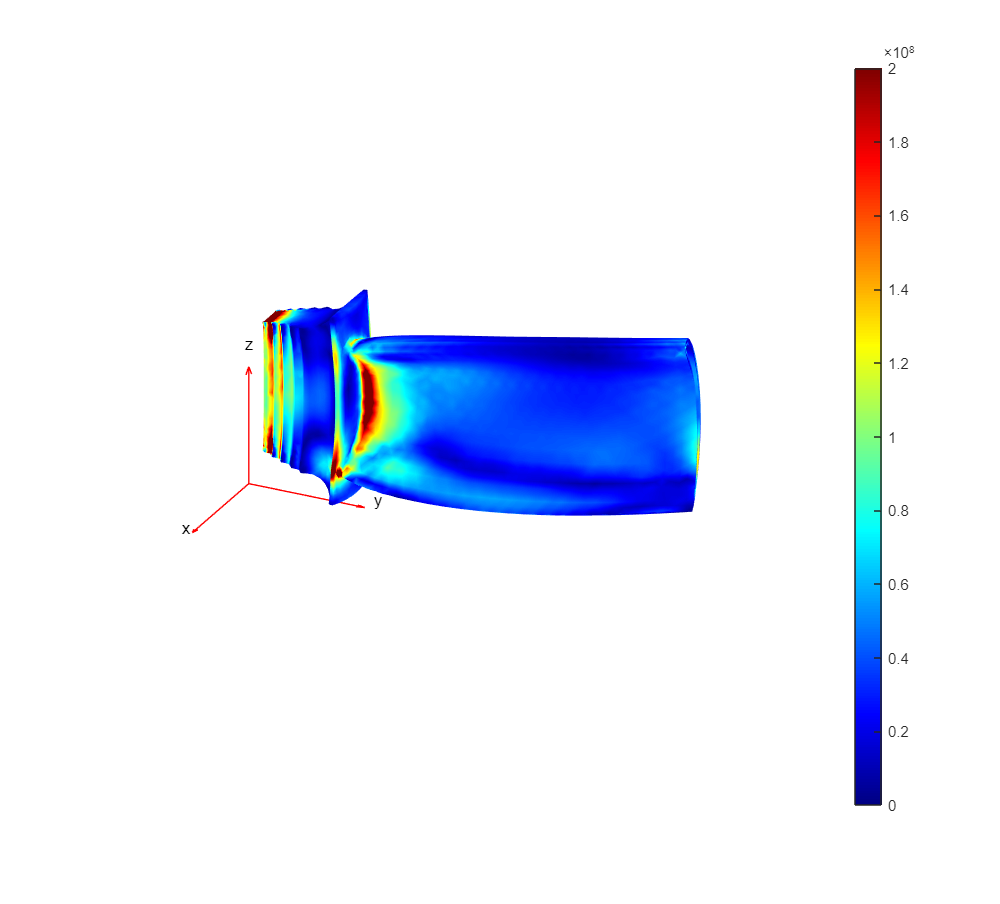

figure("units","normalized","outerposition",[0 0 1 1]);
pdeplot3D(tsmodel,"ColorMapData",Rts.VonMisesStress, ...
                  "Deformation",Rts.Displacement, ...
                  "DeformationScaleFactor",100)
caxis([0, 200e6])
view([116,25]);

Evaluate the displacement at the tip. In the design of the cover, this displacement must be taken into account to avoid friction between the cover and the blade.

max(Rts.Displacement.Magnitude)

ans = 0.0015

## Combined Pressure Loading and Thermal Stress

Compute the stress and deformations caused by the combination of thermal and pressure effects.

Use the same model as for the thermal stress analysis. Add the pressure load on the pressure and suction sides of the blade. This pressure is due to the high-pressure gas surrounding these sides of the blade.

% Pressure side
structuralBoundaryLoad(tsmodel,"Face",11, ...
                               "Pressure",p1);
% Suction side 
structuralBoundaryLoad(tsmodel,"Face",10, ...
                               "Pressure",p2);

Solve the model.

Rc = solve(tsmodel);

Plot the von Mises stress and the displacement. Specify a deformation scale factor of 100 to better visualize the deformation.

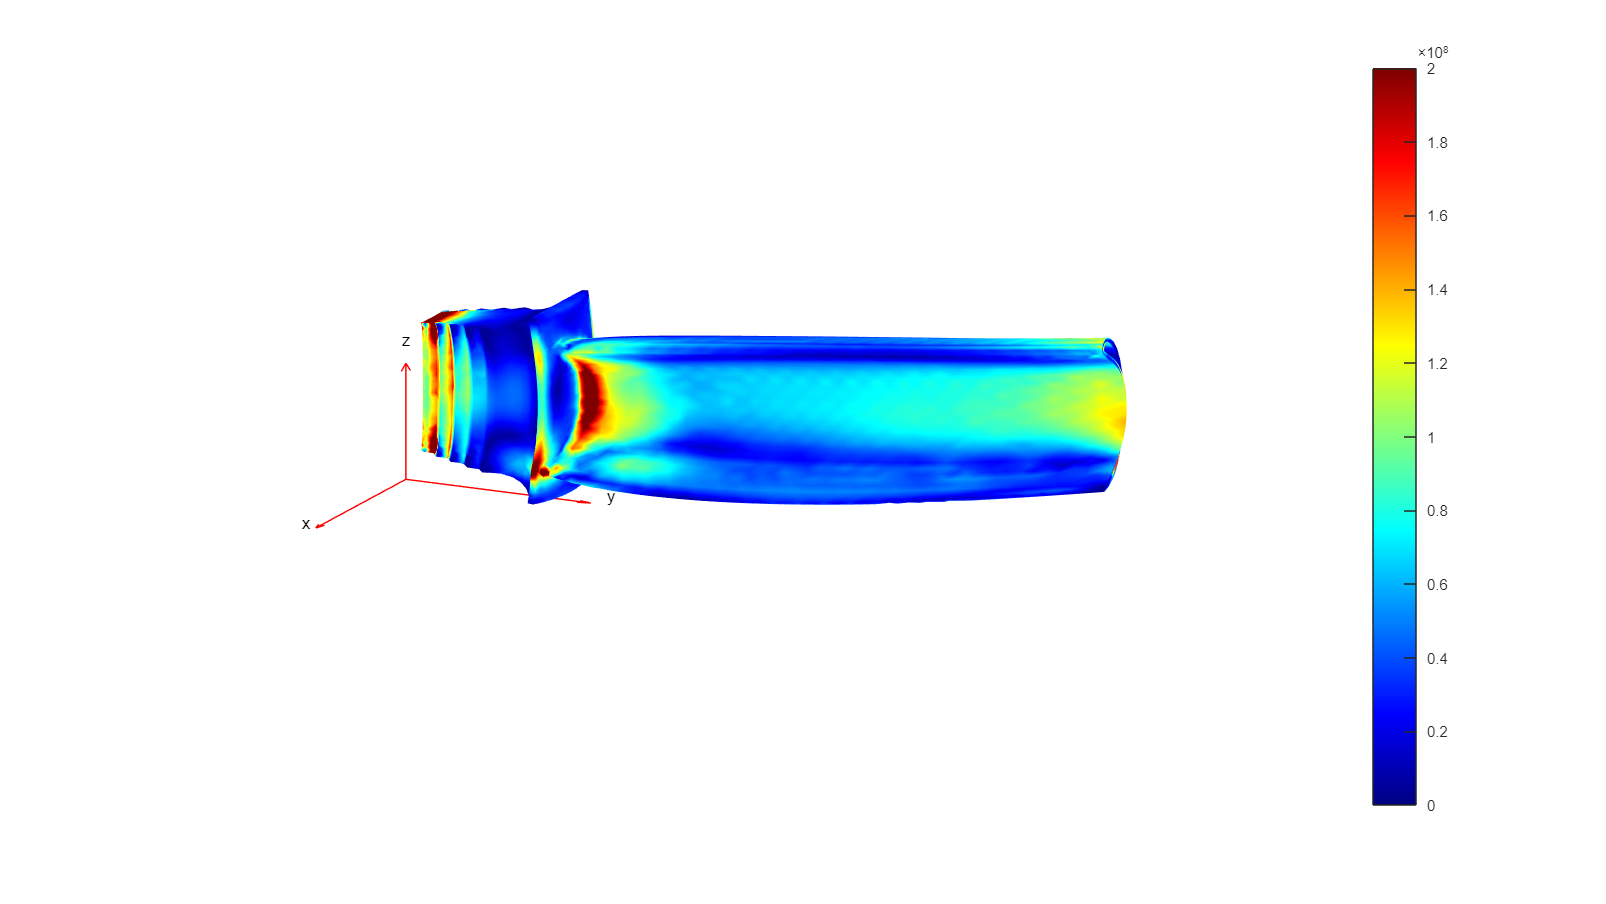

figure("units","normalized","outerposition",[0 0 1 1]);
pdeplot3D(tsmodel,"ColorMapData",Rc.VonMisesStress, ...
                  "Deformation",Rc.Displacement, ...
                  "DeformationScaleFactor",100)
caxis([0, 200e6])
view([116,25]);

Evaluate the maximum stress and maximum displacement. The displacement is almost the same as for the thermal stress analysis, while the maximum stress, 854 MPa, is significantly higher.

max(Rc.VonMisesStress)

ans = 9.8378e+08

max(Rc.Displacement.Magnitude)

ans = 0.0015

*Copyright 2019 The MathWorks, Inc.*